# AERO4600 Automatic Flight Control Systems Main file

clc
clear
close all
%%
% States
% [u,v,w,p,q,r,\phi,\theta,\psi,X,Y,Z]
%
% Inputs 
% [thrust, elevator, aileron, rudder, flaps]

## Initial Set Up

FlightData = LoadFlightData_aircraft2_75kts_CG2();

load ICs_aircraft2_75Kts_CG2

DT = 0.01;          % Integration time interval
T0 = DT;            % Simulation start time
TF = 200;            % Termination time for simulation
n_pts = round((TF-T0)/DT+1);
X = zeros(12,n_pts);
U = zeros(5,n_pts);
T = zeros(1,n_pts);

X(:,1) = X0;
U(:,1) = U0;
T(1)   = DT;


## Trim Condition

Xg    = zeros(6,1);
V_trim  = sqrt(X0(1)^2+X0(2)^2+X0(3)^2); % (m/s)
alt0    = -X0(12); % (m)
alt0ft  = alt0/0.3048; % (ft)
alpha_0 = X0(3)/V_trim; % (rad)
beta_0  = 0/57.3; % (rad)
gamma   = 0/57.3; % (rad)
phi_0   = 0/57.3; % (rad)
dp      = U0(1); % (fraction of travel 0-1)
de      = U0(2); % (rad)
da      = U0(3)/57.3; % (rad)
dr      = U0(4)/57.3; % (rad)
df      = U0(5); % (rad)

## Q1a

The design of an autopilot using elevator to directly control vertical speed will be kinda? easy, as seen in the root locus plot bc:

- one pole on RHS of plot, meaning open loop system has unstable poles (it is stable when all poles are negative real)

As gain increase, poles move left which helps stabilises the system.

Adding a zero to the system with a PD control would alos ove poles left and increase damping - so kinda easy?

% Elevator - VS TF
[A,B] = peturbAB(X0,Xg,U0,FlightData);
A_lon = A([1 3 5 8],[1 3 5 8]);     % [u w q \theta] 
B_lon = B([1 3 5 8], 1:2);          % [dT de]
A_lat = A([2 4 6 7 9],[2 4 6 7 9]);
B_lat = B([2 4 6 7 9], [3 4]);

C = [0 -1 0 V_trim];    % Vertical Speed

[Num, Den] = ss2tf(A_lon, B_lon, C, [0 0],2);
Num(abs(Num) < 1e-07) = 0;
de2vs = minreal(tf(Num, Den));
de2vs = zpk(de2vs)

de2vs =
 
        8.57 (s-16.89) (s+12.79) (s+0.04162)
  ------------------------------------------------
  (s^2 + 0.03407s + 0.06989) (s^2 + 4.67s + 10.92)
 
Continuous-time zero/pole/gain model.



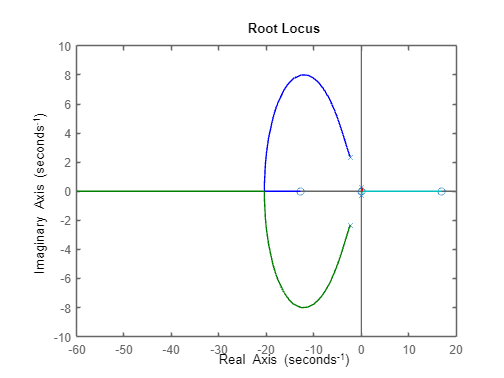

rlocus(de2vs)

## Q 2 a

s = tf('s');
% Elevator - pitch rate TF
C = [0 0 1 0]; 
[Num, Den] = ss2tf(A_lon, B_lon, C, [0 0],2);
Num(abs(Num) < 1e-07) = 0;
de2q = minreal(tf(Num, Den));
de2q = zpk(de2q)

de2q =
 
          -26.397 s (s+1.767) (s+0.08172)
  ------------------------------------------------
  (s^2 + 0.03407s + 0.06989) (s^2 + 4.67s + 10.92)
 
Continuous-time zero/pole/gain model.



stepinfo(de2q)

ans = struct with fields:
         RiseTime: 8.8818e-16
    TransientTime: 205.1423
     SettlingTime: NaN
      SettlingMin: -2.9246
      SettlingMax: 3.5822
        Overshoot: 4.0972e+17
       Undershoot: 6.7277e+17
             Peak: 5.8820
         PeakTime: 0.5916


OS = 0.02; % not actually sure if this is what he means
zeta = -log(OS) /sqrt (pi^2 + (log(OS))^2); % required damping to meet OS
w_n = 4/3*zeta;
eps = asind(zeta);
sigma = -w_n *sin(eps);
eig = sigma + 1.03960435654943i

eig = -0.8563 + 1.0396i

conj(eig)

ans = -0.8563 - 1.0396i

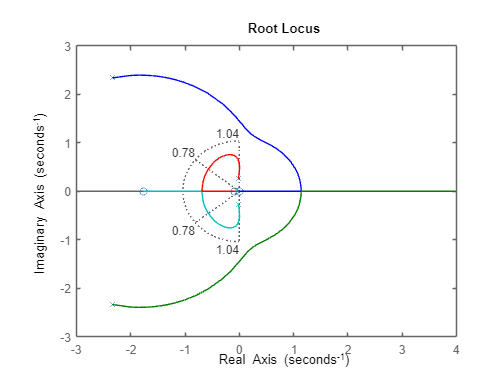

figure
rlocus(de2q)
sgrid(zeta, w_n)

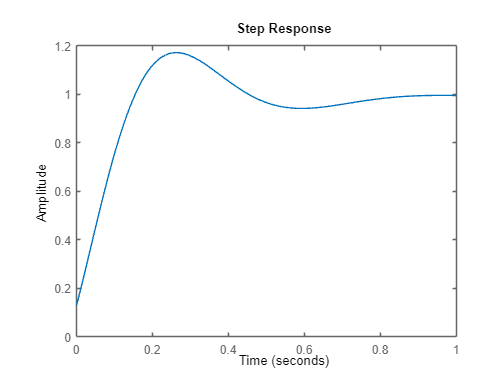

%sisotool ('rlocus',de2q)
%[k,poles] = rlocfind(de2q)

k = -4.517 * (((1+(0.035*s))*(1+(0.035*s)))/s);
sys_cl = k*de2q/(1+k*de2q);
figure
step(sys_cl)

stepinfo(sys_cl)

ans = struct with fields:
         RiseTime: 0.1267
    TransientTime: 0.7403
     SettlingTime: 0.7300
      SettlingMin: 0.9058
      SettlingMax: 1.1724
        Overshoot: 18.8560
       Undershoot: 0
             Peak: 1.1724
         PeakTime: 0.2613


function [A,B] = peturbAB(X0,Xg,U0,FlightData)

A = zeros(12,12);
B = zeros(12,5);
delta_x = 1e-6; % Perturbation for finite difference

% Compute Xdot at the trim condition
[ForceCoeff, MomentCoeff] = aero4600_aero(X0,Xg, X0, U0, FlightData);
Xdot0 = aero4600_motion(X0, ForceCoeff, MomentCoeff, FlightData);

% A Matrix
for i = 1:12
    X_perturb = X0;
    X_perturb(i) = X_perturb(i) + delta_x; %Adding a small peturbation away from equilibrium
    
    % Calculating Xdot with perturbed state
    [ForceCoeff_pert, MomentCoeff_pert] = aero4600_aero(X_perturb, Xg, X_perturb, U0, FlightData);
    Xdot_pert = aero4600_motion(X_perturb, ForceCoeff_pert, MomentCoeff_pert, FlightData);
    A(:, i) = (Xdot_pert - Xdot0) / delta_x;
end

% B matrix
for i = 1:5
    U_perturb = U0;
    U_perturb(i) = U_perturb(i) + delta_x;

    [ForceCoeff_pert, MomentCoeff_pert] = aero4600_aero(X0, Xg, X0, U_perturb, FlightData);
    Xdot_pert = aero4600_motion(X0, ForceCoeff_pert, MomentCoeff_pert, FlightData);
    B(:, i) = (Xdot_pert - Xdot0) / delta_x;
end

end